%%%%%%%% User Input  %%%%%%%
t = linspace(1, 20, 1086); t=t';  % (!) 0 있으면 indeterminate % ★ 계속 사용

x1 = 60; x2 = 3; x3 = 70;  
z1 = 5; z2 = 3; z3 = 9; z4 = 5/2; z5 = 49;

y_byF = x1/20 * sin(2*pi*x2/10*t) + x3/10*log(t);  % ★ 계속 사용
y_byG = z1*z2/5 * cos(2*pi*sqrt(z3)/10*(t+z4)) + sqrt(z5)*log(t); 

numSamplesToGen = 15;

distrib1 = 'Normal';
distrib1_1stpara = 1;
distrib1_2ndpara = 0.01;

distrib2 = 'Normal';
distrib2_1stpara = 0;
distrib2_2ndpara = 0.01;

data_tag = date

data_tag = '24-May-2022'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 하단에 %%%% ★변경 %%%% 에 유의

## 출력 곡선 동일한지 확인

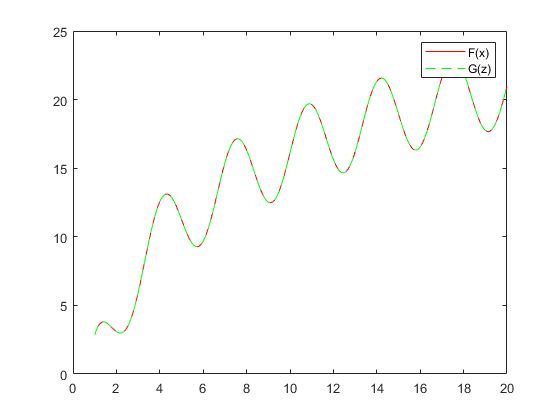

figure; 

plot(t, y_byF, 'r', 'DisplayName', 'F(x)')
hold on
plot(t, y_byG, '--g', 'DisplayName', 'G(z)')
legend

xlim([0, 20]); ylim([0, 25]);

clf;

## 불확실성 인가해서 데이터 만들기

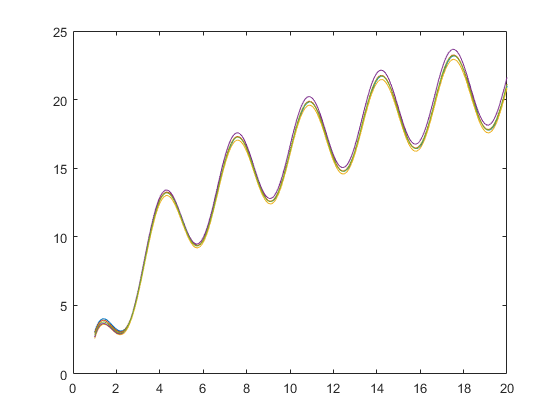

Y_by_F_uncer = [];

uncerSamp = [];

figure; 
 
for ii = 1:numSamplesToGen  % ii는 안 쓰지만 그냥 루프 여러번 하려고 
    pd1 = makedist(distrib1, distrib1_1stpara, distrib1_2ndpara);  
    uncerSamp = random(pd1, 1);  % 스칼라 랜덤 수치
    pd2 = makedist(distrib2, distrib2_1stpara, distrib2_2ndpara);
    uncerSamp2 = random(pd2, 1);
    uncerSamp3 = random(pd2, 1);
    %%%%%%%%%% ★ 변경 %%%%%%%%%%
    Y_by_F_uncerSamp = uncerSamp * (x1/20 * sin(2*pi*x2/10*(t-uncerSamp2)) + x3/10*log(t-uncerSamp3));
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    Y_by_F_uncer = [Y_by_F_uncer, t, Y_by_F_uncerSamp];  
end 

% % 확인차 5개 시각화
for i = 1:5
    plot(Y_by_F_uncer(:, i*2-1), Y_by_F_uncer(:, i*2))
    hold on
end 

xlim([0, 20]); ylim([0, 25]);

clf;

% % % 내보내기
writematrix(Y_by_F_uncer, strcat('Y_by_F_uncer_', data_tag, '.xlsx'))

% % % % 지정해서 불러오기
% Y_by_F_uncer = readmatrix(

## 1번째 WIFac 구하기

first_WIFacs = [];
% first_RMSEs = [];  % WIFac 대신에 RMSE로 유사도를 확인했었음

figure; 
 
for i = 1:numSamplesToGen
    first_WIFacs = [first_WIFacs, funcWIFac(t, y_byF, Y_by_F_uncer(:, i*2-1), Y_by_F_uncer(:, i*2))];
%     first_RMSEs = [first_RMSEs, sqrt(mean((y_byF - Y_by_F_uncer(:, i*2)).^2))]; 
    plot(Y_by_F_uncer(:, i*2-1), Y_by_F_uncer(:, i*2), 'k', 'LineWidth', 0.5)
    hold on
end
myplot = plot(t, y_byF, 'r', 'LineWidth', 2);  % 'DisplayName', 'y');

first_WIFacs 

first_WIFacs =     0.9917    0.9907    0.9933    0.9740    0.9931    0.9969    0.9860    0.9870    0.9948    0.9971    0.9903    0.9883    0.9964    0.9830    0.9962


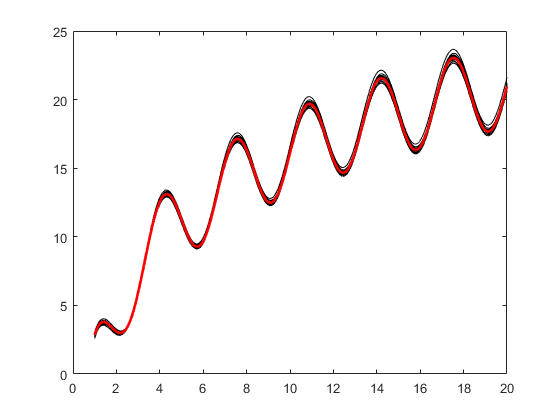

% first_RMSEs
xlim([0, 20]); ylim([0, 25]);

clf

AATable = table([first_WIFacs, mean(first_WIFacs)])  % WIFac들과 그것들의 평균

AATable = table
        Var1     
    _____________

    [1×16 double]
